# **Digital Communication**

## **Initialization)**

clc;clear;
rng(1)
dcl_init;

## **Bit Generation)**

if flg_add_hdr == 1
    hder_bit = repmat(reshape(de2bi(hex2dec(['1C6387FF5DA4FA325C895958DC5']'))', [], 1),1,k);
    b_tx = [hder_bit; bit_gen(pkt_size, k)];
else
    hder_bit = 0;
    b_tx = bit_gen(pkt_size, k);
end

## **Gray Codding)**

[b_gray] = gray_code(flg_gray_encode,k)

b_gray =      0     0     0     0
     0     0     0     1
     0     0     1     1
     0     0     1     0
     0     1     1     0
     0     1     1     1
     0     1     0     1
     0     1     0     0
     1     1     0     0
     1     1     0     1


for i = 1 : length(b_tx)
    [~,sym_idx(i)] = min(abs(bi2de(b_tx(i, :)) - bi2de(b_gray)));
end
sym_idx = sym_idx.';

## **Transmitter)**

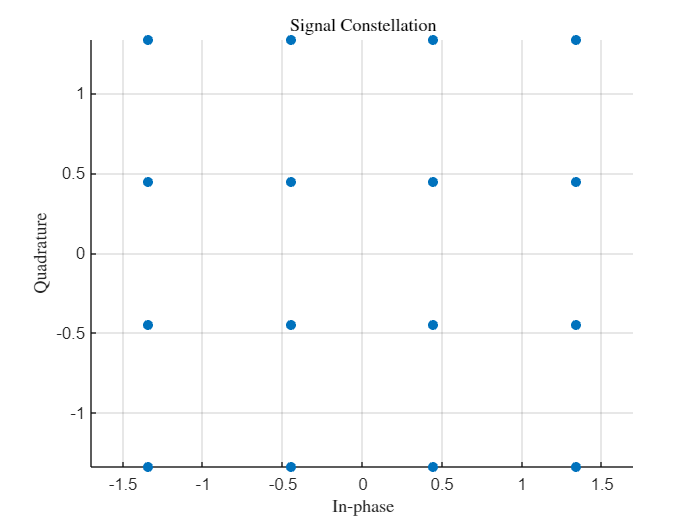

[tx_smpl , cons] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, modulation_type);
figure
scatter(real(cons), imag(cons), 'filled');
axis('equal');
xlabel('In-phase',Interpreter='latex');
ylabel('Quadrature',Interpreter='latex');
title('Signal Constellation',Interpreter='latex');
grid on

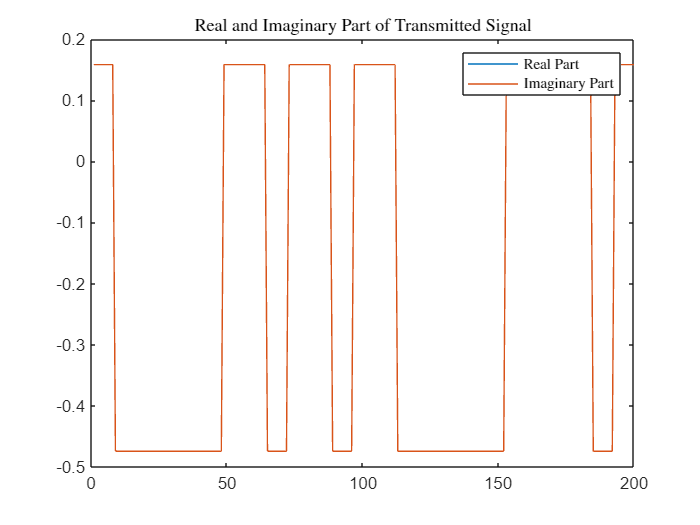

figure
plot(real(tx_smpl(1:200,:)))
hold on
plot(imag(tx_smpl(1:200,:)))
title('Real and Imaginary Part of Transmitted Signal',Interpreter='latex')
legend('Real Part','Imaginary Part',Interpreter='latex')

hdr_smpl = tx_smpl(1 : size(hder_bit,1) * smpl_per_symbl);

## Channel Transmission)

tx_smpl_delayed = [zeros(chnl_delay_in_smpl,1) ; tx_smpl];
rx_smpl = tx_smpl_delayed.*exp(1j*chnl_phase_offset);

Es_avg = 1;
Eb = Es_avg/k;
snr_db_ = 10;
snr_lin_ = 10.^(snr_db_/10);
N0 = Eb./snr_lin_;
var_noise = (N0/2);
noise = randn(length(tx_smpl_delayed), 1)*sqrt(var_noise) + 1j.*randn(length(tx_smpl_delayed), 1)*sqrt(var_noise);
rx_smpl_noise = rx_smpl + noise;

## **Recevier)**

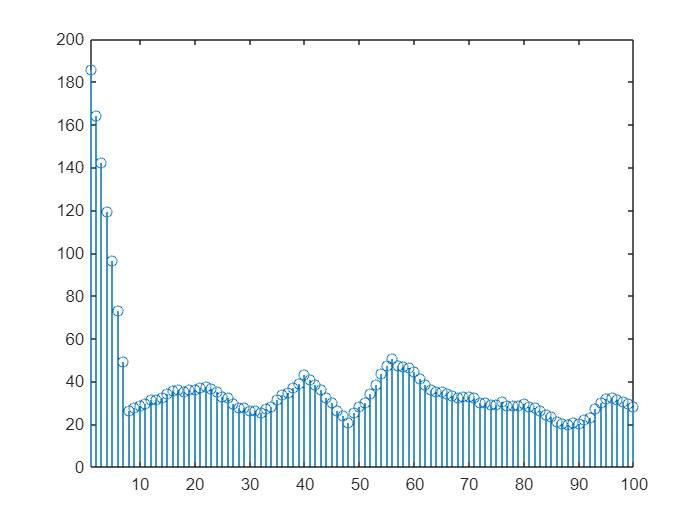

if rx_alg == 1
    [c,lag] = xcorr(rx_smpl_noise,hdr_smpl);
    c = c(lag>=0);
    lag = lag(lag>=0);
    figure
    stem(lag,abs(c))
    xlim([1 100])
    [val, idx] = max(abs(c));
    phase_comp = -angle(val);
    rx_smpl_noise = rx_smpl_noise(idx : end);
    switch cmpnst_mode
        case cmpnst_mode == 1
        [val_amp, ~] = xcorr(hdr_smpl, tx_smpl);
        amp_comp = abs(max(val_amp))/abs(val);
        rx_smpl_noise = rx_smpl_noise.*amp_comp;
        case cmpnst_mode == 2
        rx_smpl_noise = rx_smpl_noise.*exp(-1j*phase_comp);        
        case cmpnst_mode == 3
        rx_smpl_noise = rx_smpl_noise.*exp(-1j*phase_comp);
        [val_amp, ~] = xcorr(hdr_smpl, tx_smpl);
        amp_comp = abs(max(val_amp))/abs(val);
        rx_smpl_noise = rx_smpl_noise.*amp_comp;
    end
end

[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_noise, ... 
            modulation, M, fs, smpl_per_symbl, pulse_name , ...
            rx_mode, pkt_size, beta, span_in_symbl);
det_bit = b_gray(det_sym_idx, :);
ber = length(find(det_bit ~= b_tx))/numel(b_tx);

display(['BER=' , num2str(ber)])

BER=0


% figure
% plot((rx_sym(:, 1)), (rx_sym(:, 2)), 'o')
% grid on
% title([num2str(delay),' Symbol Delay'])
% axis equal

## **Bit Error Rate)**

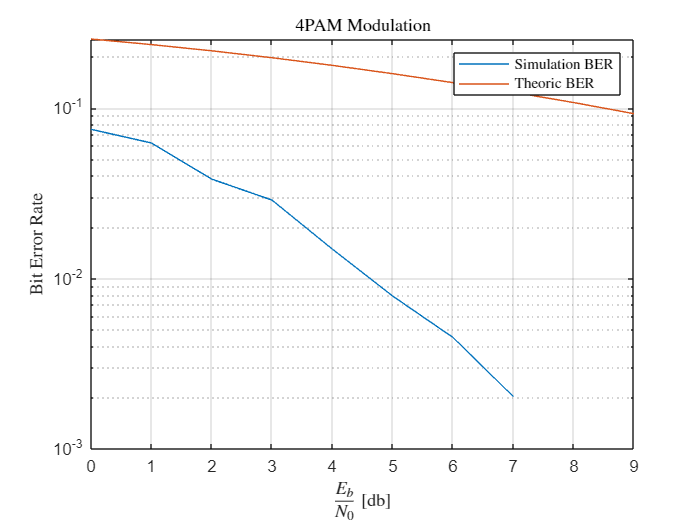

for i = snr_db
    snr_lin = 10.^(snr_db(i+1)/10);
    N0 = Eb./snr_lin;
    var_noise = (N0/2); 
    noise = randn(length(tx_smpl), 1)*sqrt(var_noise) + 1j.*randn(length(tx_smpl), 1)*sqrt(var_noise);
    rx_smpl_noise = tx_smpl + noise;
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_noise, ... 
            modulation, M, fs, smpl_per_symbl, pulse_name , ...
            rx_mode, pkt_size, beta, span_in_symbl);
    det_bit = b_gray(det_sym_idx, :);
    ser(i+1) = length(find(det_sym_idx ~= sym_idx))/length(sym_idx);
    ber(i+1) = length(find(det_bit ~= b_tx))/numel(b_tx);
end
figure
semilogy(snr_db, ber, snr_db, berawgn(snr_db,'pam',M,'coherent'))
legend('Simulation BER ','Theoric BER','Interpreter','latex')
title('4PAM Modulation','Interpreter','latex')
xlabel('$\frac{E_b}{N_0}$ [db]',"Interpreter","latex")
ylabel('Bit Error Rate',"Interpreter","latex")
grid on

# **Functions:**

## **Bit Generation)**

function bits = bit_gen(pkt_size, k)
    bits = randi([0 1], pkt_size, k);
end

## **Gray Codding)**

function [b_gray] = gray_code(flg_gray_encode,k)
    if (flg_gray_encode)
        A = [0 ; 1];
        for i = 2 : k
            A = [zeros(2^(i-1),1) A; ones(2^(i-1),1) flipud(A)];
        end
        b_gray = A;
    else
        A = [0 ; 1];
        for i = 2 : k
            A = [zeros(2^(i-1),1) A; ones(2^(i-1),1) A];
        end
        b_gray = A;
    end
end

## **Constellation)**

function [cons, Es_avg] = constellation(M, modulation)
    modulation = lower(modulation);
    switch modulation
    case 'pam'
            cons = (-(M-1):2:(M-1))';
            Es_avg = abs(cons'*cons)/M;
            cons = cons/sqrt(Es_avg);
            
        case 'psk'
            cons = ((0:M-1)*2*pi/M)';
            cons = exp(1j.*cons);
            cons = cons/sqrt(abs(cons'*cons)/M);
            Es_avg = abs(cons'*cons)/M;
 
        case 'qam'
            k = log2(M);
            m = 2^(floor(k/2));
            n = 2^(ceil(k/2));
            x = constellation(m, 'pam');
            y = constellation(n, 'pam');
            cons = x + 1j*y';
            for i=2:2:size(cons,2)
                cons(:,i) = flipud(cons(:,i));
            end
            cons = cons(:);
            Es_avg = abs(cons'*cons)/M;
    end
    
end

## **Pulse Shape)**

function [p, t] = pulse_shape(pulse_name, fs, smpl_per_symbl, varargin)
% smpl_per_symbl: Samples per Symbol
% fs: Baseband Sampling Frequency
% 'pulse_name' Options:  
%      rectangular
%      triangular
%      sine
%      raised_cosine
%      root_raised_cosine
%      gaussian

% For 'raised_cosine', 'root_raised_cosine', 'gaussian' two excess options is required
%      'beta': rolloff factor.
%      'span_in_symbl': the truncated interval of pulse

    ts = 1/fs;              % Baseband Sampling Period
    Ts = smpl_per_symbl*ts; % Pulse Duration
    pulse_name = lower(pulse_name);
    if nargin == 3
        t = (0:smpl_per_symbl-1)' * ts;
        switch pulse_name
            case 'rectangular'
                p = 1/sqrt(Ts) * ones(length(t),1);
            case 'triangular'
                p = max(Ts/2-abs(t-Ts/2),0);
            case 'sine'
                p = sin(pi*(t/Ts));
        end
    elseif nargin == 5
        beta_ = varargin{1};
        span_in_symbl_ = varargin{2};
        t = (0:span_in_symbl_*smpl_per_symbl - 1)'*ts - span_in_symbl_/2*Ts;
        switch pulse_name
            case 'raised_cosine'
                p = sinc(t/Ts) .* (cos(pi*beta_*t/Ts)) ./ (1-(4*(beta_^2)*(t.^2))/(Ts^2));
                p(t==Ts/(2*beta_)) = (pi/4)*sinc(1/(2*beta_));
                p(t==-Ts/(2*beta_)) = (pi/4)*sinc(1/(2*beta_));
            case 'root_raised_cosine'
                p =  1/sqrt(Ts) * (sin(pi*t/Ts*(1-beta_))+4*beta_*t/Ts.*cos(pi*t/Ts*(1+beta_))) ./ (pi*t/Ts.*(1-(4*beta_*t/Ts).^2));
                p(t == 0) = (1/sqrt(Ts)) * (1-beta+4*beta/pi);
                p(t == Ts/(4*beta_) | t == -Ts/(4*beta_)) = beta_/(sqrt(2*Ts)) * ((1+2/pi)*sin(pi/(4*beta_))+(1-2/pi)*cos(pi/(4*beta_)));
            case('gaussian')
                p = (qfunc(2*pi*beta_*(t-Ts/2))-qfunc(2*pi*beta_*(t+Ts/2)))/log(2);
        end
    end
    Ep = abs(p' * p);
    p = p / sqrt(Ep);
end

## **Pulse Modulation)**

function [tx_smpl, cons] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name , pulse_shape_mode, varargin)
    pulse_shape_mode = lower(pulse_shape_mode);
    if nargin == 7
        [cons,~] = constellation(M, modulation);
        mod_sym = cons(sym_idx);
        [p, ~] = pulse_shape(pulse_name, fs, smpl_per_symbl);
        switch pulse_shape_mode
            case 'kron'
                tx_smpl = kron(mod_sym, p);
            case 'conv'
                mod_sym_upsample = upsample(mod_sym,smpl_per_symbl);
                tx_smpl = conv(mod_sym_upsample(1:end-(smpl_per_symbl-1)), p);
        end
    else
        beta_ = varargin{1};
        span_in_symbl_ = varargin{2};
        [cons,~] = constellation(M, modulation);
        mod_sym = cons(sym_idx);
        [p, ~] = pulse_shape(pulse_name, fs, smpl_per_symbl,beta_,span_in_symbl_);
        switch pulse_shape_mode
            case 'kron'
                tx_smpl = kron(mod_sym, p);
            case 'conv'
                mod_sym_upsample = upsample(mod_sym,smpl_per_symbl);
                tx_smpl = conv(mod_sym_upsample(1:end-(smpl_per_symbl-1)), p);
        end
    end
end

## **Detection)**

function [rx_sym] = corr_match(rx_smpl, p, smpl_per_symbl, rx_mode, span_in_symbl)
    if strcmp(rx_mode, 'correlator')
        rx_sym = zeros(length(rx_smpl)/smpl_per_symbl,1);
        for i = 1 : length(rx_smpl)/smpl_per_symbl
            rx_sym(i) = p'*rx_smpl(((i-1)*smpl_per_symbl)+1:i*smpl_per_symbl);
        end
        rx_sym = rx_sym.';
    elseif strcmp(rx_mode, 'matched_filter')
        span_in_smpl = smpl_per_symbl * span_in_symbl; 
        temp = conv(rx_smpl, flip(conj(p)));
        rx_sym = temp(span_in_smpl:smpl_per_symbl:end);
        rx_sym = rx_sym(1:length(rx_smpl));
    end
end

## **Minimum Distance Detector)**

function [det_sym, det_sym_idx] = min_dist_detector(rx_sym, constellation)
    det_sym = zeros(length(rx_sym),1);
    det_sym_idx = zeros(length(rx_sym),1);
    for i = 1 : length(det_sym)
        [~,det_sym_idx(i)] = min(abs(constellation-rx_sym(i)));
    end
    det_sym = constellation(det_sym_idx);
end

## **Demodulation)**

function [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name, rx_mode, pkt_size, beta, span_in_symbl)
    if strcmp(pulse_name, 'rectangular') || strcmp(pulse_name, 'triangular') || strcmp(pulse_name, 'sine')
        [p, ~] = pulse_shape(pulse_name, fs, smpl_per_symbl);
        [cons, ~] = constellation(M, modulation);
        [rx_sym] = corr_match(rx_smpl, p, smpl_per_symbl, rx_mode, span_in_symbl);
        [~, det_sym_idx] = min_dist_detector(rx_sym, cons);
    else
        [p, ~] = pulse_shape(pulse_name, fs, smpl_per_symbl, beta, span_in_symbl);
        [cons, ~] = constellation(M, modulation);
        [rx_sym] = corr_match(rx_smpl, p, smpl_per_symbl, rx_mode, span_in_symbl);
        [~, det_sym_idx] = min_dist_detector(rx_sym, cons);
    end
end